# Integrazione Numerica per il Sistema dei due Gamberi

Ricordiamo le equazioni che definiscono il nostro sistema dinamico


$$\dot Z= c_1F-m_1 Z -\gamma_2 LZ-\gamma_1GZ-a_3 Z^2$$



$$\dot F= c_2(LZ\gamma_2  +\lambda \gamma_1 GZ)- m_2 F$$



$$\dot G= -\gamma_1 GZ - a_1 LG+b_1 G -m_3 G^2$$



$$\dot L=  -a_2LG+b_2 L -m_4 L^2$$


Fissiamo il tempo massimo in cui studiare il sistema, e i valori iniziali delle $4$ popolazioni

% le soluzioni vivono nel primo quadrante
format short
options = odeset('NonNegative',[1,2,3,4]);


% fissa il tempo d'integrazione
tmax=13

tmax = 13

% integra in [0 tmax]
t_span=[0,tmax];

% condizioni iniziali
Z0=20;G0=27;
F0=16;L0=16;
init=[Z0;F0;G0;L0]; 

Definiamo i nostri parametri, è possibile utilizzare configurazioni preimpostate in cui vi è la stabilità o bistabilità degli equilibri indicati, oppure configurare manualmente i parametri per studiare il sistema come più ci piace.

% Scegli l'opzione di configurazione
conf="E3";
if (conf=="configura manualmente")
g1=0.3822914034;g2=0.007;
a1=20;a2=0.2;
a3=0.2;lambda=0.05;
b1=40;b2=4;
c1=10;c2=10;
m1=20;m2=1;
m3=0.2;m4=6;
else
[a1,a2,a3,b1,b2,c1,c2,m1,m2,m3,m4,lambda,g1,g2]=config(conf);
end

Una tabellina riassuntiva ci permette di vedere i valori dei nostri parametri, utile se si sceglie di utilizzare quelli pre-impostati

params_names=["a1","a2","a3","lambda","b1","b2","c1","c2","m1","m2","m3","m4","g1","g2"]';
param_values=[a1,a2,a3,lambda,b1,b2,c1,c2,m1,m2,m3,m4,g1,g2]';
T=table(params_names,param_values)

T = 14×2 table
    params_names    param_values
    ____________    ____________

      "a1"                0.2   
      "a2"                0.2   
      "a3"                  4   
      "lambda"          0.005   
      "b1"                 19   
      "b2"                 19   
      "c1"                 45   
      "c2"                  3   
      "m1"                 40   
      "m2"                 15   
      "m3"                  1   
      "m4"                  1   
      "g1"             0.0007   
      "g2"            0.00075   


% Definizione delle equzioni e del sistema dinamico
eq1=@(Z,F,G,L) c1*F-m1*Z-g2*L.*Z-g1*G.*Z-a3*Z.^2;
eq2=@(Z,F,G,L) c2*(g2*L.*Z+lambda*g1*G.*Z)-m2*F;
eq3=@(Z,F,G,L) -g1*G.*Z-a1*G.*L+b1*G-m3*G.^2;
eq4=@(Z,F,G,L) -a2*L.*G+b2*L-m4*L.^2;
Func=@(t,X) [eq1(X(1),X(2),X(3),X(4));eq2(X(1),X(2),X(3),X(4));eq3(X(1),X(2),X(3),X(4));eq4(X(1),X(2),X(3),X(4))];

Integriamo numericamente il sistema e plottiamo le popolazioni al variare del tempo, inoltre analizziamo la stabilità teorica di tutti gli equilibri, per vedere se corrisponde alla simulazione

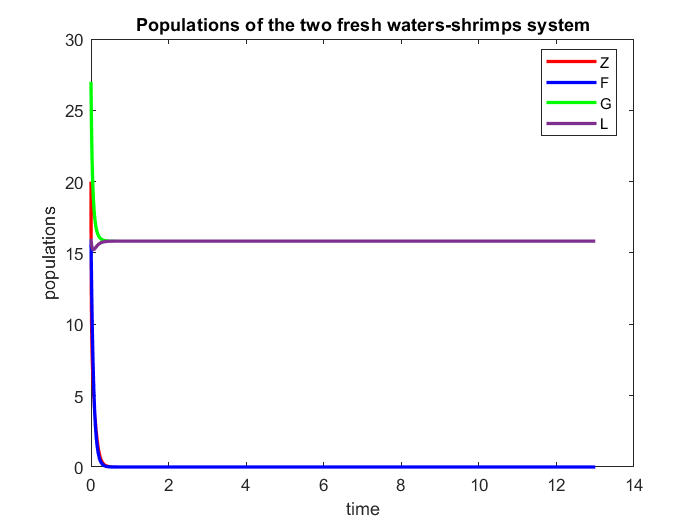

% Integrazione numerica del sistema tramite ode45
[t,y]=ode45(Func,t_span,init,options);
Z=y(:,1);
F=y(:,2);
G=y(:,3);
L=y(:,4);

% plottiamo le popolazioni al variare del tempo
figure
plot(t,Z,"-r",'LineWidth',2)
hold on
plot(t,F,"-b",'LineWidth',2)
hold on
plot(t,G,"-g",'LineWidth',2)
hold on
plot(t,L,"-",'LineWidth',2)
legend("Z","F","G","L","location","best")
xlabel('time')
ylabel('populations')
title("Populations of the two fresh waters-shrimps system")

% Studio di ammissibilità e stabilità degli equilibri del sistema
[s0,s1,s2,s3,s4,s5,s6,lista]=stabilita(a1,a2,a3,b1,b2,c1,c2,m1,m2,m3,m4,lambda,g1,g2);
Eqnames = {'E0','E1','E2','E3','E4','E5','E6'};
Stab=[s0,s1,s2,s3,s4,s5,s6];
T=table(Eqnames',Stab');
T.Properties.VariableNames = {'Equilibri','Stabilita'}

T = 7×2 table
    Equilibri        Stabilita    
    _________    _________________

     {'E0'}      "instabile"      
     {'E1'}      "instabile"      
     {'E2'}      "instabile"      
     {'E3'}      "stabile"        
     {'E4'}      "non ammissibile"
     {'E5'}      "non ammissibile"
     {'E6'}      "non ammissibile"


Per osservare meglio la stabilità dei vari equilibri, ed i casi di bistabilità, rappresentiamo il diagramma delle fasi, o meglio, una proiezione di quest'ultimo. Per i primi tre equilibri E1,E2,E3, la proiezione avviene sul piano $G,L$, per i successivi $3$ e nei casi di bistabilità, invece, scegliamo di plottare lo spazio $Z,F,G$. Di seguito indicare il numero di traiettorie da plottare nello spazio delle fasi, i dati iniziale sono in parte stocastici, ed in parte corrispondenti alle condizioni iniziali precedenti, ove manca l'asse relativo a tale popolazione nella proiezione. Stampiamo anche una tabella col valore teorico degli equilibri stabili

index=30

index = 30

insta=true;


figure

% opzioni integrazione
t_span=[0,50];

% scrive gli equilibri stabili in una matrice per il disegno
Q=equilibrio(Stab,a1,a2,a3,b1,b2,c1,c2,m1,m2,m3,m4,lambda,g1,g2);





if (Q(1)==0 && Q(2)==0 && Q(3)==0 && Q(4)==0)
    Eq_stabili="Non ci sono equilibri stabili"
else
    Eq_stabili=table(Q,'RowNames',lista,'VariableNames',{'Stabili'})
end

Eq_stabili = table
                      Stabili            
          _______________________________

    E3    0         0    15.833    15.833


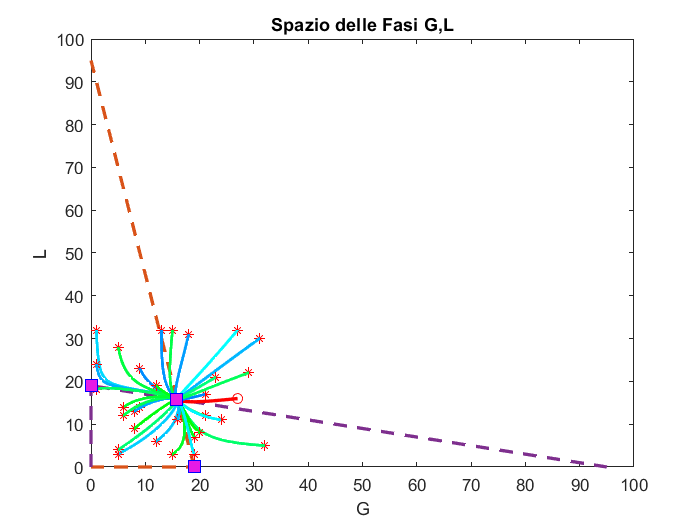

figure
if (conf=="bistabilita3" || conf=="E3")
 [tempG,tempL,GG1,GG2,LL1,LL2]=isocline(b1,b2,a1,a2,m3,m4);
 plot(tempL,GG1,'--','LineWidth',2,'Color',[0.8500 0.3250 0.0980]);
 hold on
 plot(tempL,GG2,'--','LineWidth',2,'Color',[0.8500 0.3250 0.0980]);
 hold on
 plot(LL1,tempG,'--b','LineWidth',2,'Color',[0.4940 0.1840 0.5560]);
 hold on
 plot(LL2,tempG,'--b','LineWidth',2,'Color',[0.4940 0.1840 0.5560]);
end

n=size(Q,1);

% metodo per creare punti iniziali random
% nel caso in cui tutti gli equilibri sono instabili,
% l'output di Q è (0,0,0,0)
if (Q(1)==0 && Q(2)==0 && Q(3)==0 && Q(4)==0)
    QQQ=equilibrio_instabili(Stab,a1,a2,a3,b1,b2,c1,c2,m1,m2,m3,m4,lambda,g1,g2);
    nn=size(QQQ,1);
    xm=max(ceil(sum(QQQ(:,1))/nn),10);ym=max(ceil(sum(QQQ(:,2))/nn),10);zm=max(ceil(sum(QQQ(:,3))/nn),10);wm=max(ceil(sum(QQQ(:,4))/nn),10);
else
    xm=max(ceil(sum(Q(:,1))/n),10);ym=max(ceil(sum(Q(:,2))/n),10);zm=max(ceil(sum(Q(:,3))/n),10);wm=max(ceil(sum(Q(:,4))/n),10);
end

% Definizione di un range di colori simili per il plot
if index==0
     newcolors=[0.5,1,0];
else
h=1/(2*index);
newcolors = [0,1,1];
 for col=1:index
     newcolors=[newcolors;0,1-col*h,1];
 end
 for col=index+1:2*index
     newcolors=[newcolors;0,1,1-col*h];
 end
colororder(newcolors);
end

% Nei casi in cui la malattia è nulla, plottiamo nel piano G,L
if (conf=="E3" || conf=="E2" || conf=="E1" || conf=="bistabilita3")

% Grafico dell'orbita precedentemente calcolata, in rosso
plot(G,L,'r','LineWidth',2);
hold on
plot(G0,L0,'or')
hold on
for j=1:index
    % routine per creare punti random, alcuni intorno al baricentro degli
    % equilibri, altri vicino a zero
             ytemp=max(zm+randi([-zm,zm]),1);
             ztemp=max(wm+randi([-wm,wm]),1);
             % grafico condizioni iniziali
             plot(ytemp,ztemp,'*r','MarkerSize',5)
             hold on
             % integrazione del sistema
             ivc=[Z0;F0;ytemp;ztemp];
             [t,yy]=ode45(Func,t_span,ivc,options);
             ZZ=yy(:,1);
             FF=yy(:,2);
             GG=yy(:,3);
             LL=yy(:,4);
             % grafico delle soluzioni come orbite
             plot(GG,LL,'LineWidth',2)
             hold on
end
  % Plotta gli equilibri
  plot(Q(:,3),Q(:,4),'s','MarkerSize',10,'MarkerEdgeColor','b','MarkerFaceColor',[0.9,0.1,0.9]);
  hold on 
  % Plotta anche gli equilibri instabili se scelto nel checkbox
  if (insta)
      QQ=equilibrio_instabili(Stab,a1,a2,a3,b1,b2,c1,c2,m1,m2,m3,m4,lambda,g1,g2);
      plot(QQ(:,3),QQ(:,4),'s','MarkerSize',10,'MarkerEdgeColor','b','MarkerFaceColor',[0.9,0.1,0.9]);
      hold on
  end

 hold on
  % Opzioni per il grafico
  xlabel('G')
  ylabel('L')
  title("Spazio delle Fasi G,L") 
else
% Funziona uguale, ma al posto di L plottiamo Z ed F
plot3(Z,F,G,'r','LineWidth',2);
hold on
plot3(Z0,F0,G0,'or')
hold on
  for i=1:index
             xtemp=max(xm+randi([-xm,xm]),1);
             ytemp=max(ym+randi([-ym,ym]),1);
             ztemp=max(zm+randi([-zm,zm]),1);
             plot3(xtemp,ytemp,ztemp,'*r','MarkerSize',5)
             hold on
             ivc=[xtemp;ytemp;ztemp;L0];
             [t,yy]=ode45(Func,t_span,ivc,options);
             ZZ=yy(:,1);
             FF=yy(:,2);
             GG=yy(:,3);
             LL=yy(:,4);
             plot3(ZZ,FF,GG,'LineWidth',2)
             
             hold on
  end
  plot3(Q(:,1),Q(:,2),Q(:,3),'o','MarkerSize',10,'MarkerEdgeColor','b','MarkerFaceColor',[0.9,0.1,0.9]);
  % Plotta anche gli equilibri instabili se scelto nel checkbox
  if (insta)
      QQ=equilibrio_instabili(Stab,a1,a2,a3,b1,b2,c1,c2,m1,m2,m3,m4,lambda,g1,g2);
      plot3(QQ(:,1),QQ(:,2),QQ(:,3),'o','MarkerSize',10,'MarkerEdgeColor','b','MarkerFaceColor',[0.9,0.1,0.9]);
  end
  hold on
  xlabel('F')
  ylabel('Z')
  zlabel('G')
  title("Spazio delle Fasi Z,F,G")
  % Questo solo per fare un po' di effetto alla presentazione, la
  % condizione è vera a posteriori quando arriviamo ad Hopf, e mai prima
  if (g1>0.3)
      bif=ausiliario(a1,a2,a3,b1,b2,c1,c2,m1,m2,m3,m4,lambda,g1,g2);
      title("Spazio delle Fasi Z,F,G",bif)
  end
end